# **변경사항**

**2022.02.12**

- **  singlechannel, multichannel 각각 하나의 함수로 통합**

**2022.01.25**

- `readVerticalWithoutTime` 추가

# **1. readSingleChannel**

input

- `filename`: 파일 경로를 입력. xlsx, csv 파일 둘 다 가능.

- `timeColumnIdx`: 엑셀에서 데이터 파일을 열었을 때, 시간 변수가 적혀 있는 column의 위치. 예를 들어 C행에 적혀 있으면 3, F행에 적혀 있으면 6을 입력. **시간 변수가 없는 파일의 경우 0을 입력**

- `startRowIdx`: 엑셀에서 데이터 파일을 열었을 때, 관측치 데이터가 시작하는 row의 위치

- `startColIdx`: 엑셀에서 데이터 파일을 열었을 때, 관측치 데이터가 시작하는 column의 위치

- `sampleRate`: 시간 변수가 없는 파일의 경우 sampling frequency 값을 입력. 시간 변수가 있는 파일의 경우 nan을 입력

- `organoidNum, channelNum, month`: 관리를 위한 index, 데이터 처리에 영향을 미치지 않으므로 적절히 입력

## 예제 1. MEA data.xlsx

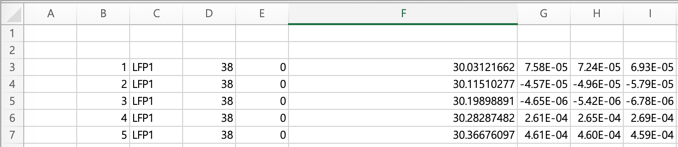

reader = channelReader();

                                    % filename,     timeColumnIdx  startRowIdx   startColIdx   sampleRate   organoidNum        channelNum     month
test_1 = reader.readSingleChannel("./data/MEA data.xlsx", 6,      3,             7,            nan,           1,              38,            1)

channel number = 38
sampling rate = 3051.757787Hz
starts at 30.031217, ends at 50.079335, duration = 20.048118
number of timestamps = 61183



test_1 =   channel - 속성 있음:

                              organoidNum: 1
                               channelNum: 38
                                    month: 1
                                       sf: 3.0518e+03
                                  msPerTs: 0.3277
                              nTimestamps: 61183
                                startTime: 30.0312
                            endTimeApprox: 50.0793
                           durationApprox: 20.0481
                             originalTime: [30.0312 30.0315 30.0319 30.0322 30.0325 30.0329 30.0332 30.0335 30.0338 30.0342 30.0345 30.0348 30.0351 30.0355 30.0358 30.0361 30.0365 30.0368 30.0371 30.0374 30.0378 30.0381 30.0384 30.0388 30.0391 … ]
                                        t: [30.0312 30.0315 30.0319 30.0322 30.0325 30.0329 30.0332 30.0335 30.0338 30.0342 30.0345 30.0348 30.0351 30.0355 30.0358 30.0361 30.0365 30.0368 30.0371 30.0374 30.0378 30.03

## 예제 2. Data 1.csv

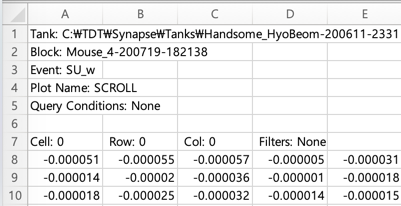

                                    % filename,     timeColumnIdx  startRowIdx  startColIdx    sampleRate     organoidNum   channelNum     month
test_2 = reader.readSingleChannel("./data/Data 1.csv",      0,       8,             1,            3152,           1,              1,         1);

파일의 마지막 열이 모두 공백 문자로 되어 있습니다. matlab은 공백 문자를 NaN으로 불러옵니다. 해당 열을 삭제했습니다.
channel number = 1
sampling rate = 3152.000000Hz
starts at 0.000000, ends at 3.248414, duration = 3.248414
number of timestamps = 10240



## 예제 3. Data 2.csv

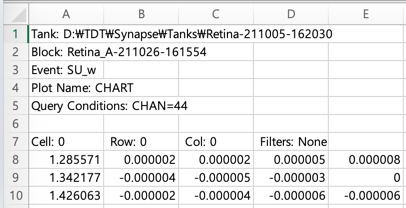

                                        % filename,    timeColumnIdx  startRowIdx   startColIdx   sampleRate     organoidNum   channelNum    month
test_3 = reader.readSingleChannel("./data/Data 2.csv",      1,            8,             2,            nan,           1,            1,        1);

파일의 마지막 열이 모두 공백 문자로 되어 있습니다. matlab은 공백 문자를 NaN으로 불러옵니다. 해당 열을 삭제했습니다.
1행의 관측치 수가 1382로, 2048개인 다른 행보다 관측치 수가 적습니다.
channel number = 1
sampling rate = 24414.062313Hz
starts at 1.285571, ends at 81.369458, duration = 80.083887
number of timestamps = 1955174



## 예제 4. 추가 data.xlsx

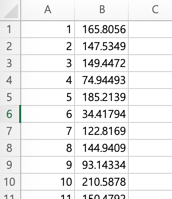

                                        % filename,     timeColumnIdx  startRowIdx   startColIdx   sampleRate     organoidNum   channelNum     month
test_4 = reader.readSingleChannel("./data/추가 data.xlsx",      0,       1,             2,            3152,           1,              1,          1);

channel number = 1
sampling rate = 3152.000000Hz
starts at 0.000000, ends at 0.031409, duration = 0.031409
number of timestamps = 100



# **2. readMultiChannelFile**

여러 채널 데이터가 포함된 파일 읽어오기

`readMultiChannelFile으로 파일 자체를 읽어옴`

- `filename`: 파일 경로를 입력. xlsx, csv 파일 둘 다 가능.

- `channelColumnIdx: `엑셀에서 데이터 파일을 열었을 때, channel 정보가 적혀 있는 column의 위치. 

- `timeColumnIdx`: 엑셀에서 데이터 파일을 열었을 때, 시간 변수가 적혀 있는 column의 위치. 예를 들어 C행에 적혀 있으면 3, F행에 적혀 있으면 6을 입력. **시간 변수가 없는 파일의 경우 0을 입력**

- `startRowIdx: `엑셀에서 데이터 파일을 열었을 때, 관측치 데이터가 시작하는 row의 위치

- `startColIdx: `엑셀에서 데이터 파일을 열었을 때, 관측치 데이터가 시작하는 column의 위치

- `sampleRate: `시간 변수가 없는 파일의 경우 sampling frequency 값을 입력. 시간 변수가 있는 파일의 경우 nan을 입력

`그 다음 아래의 두 가지 방법을 사용`

- `readSingleChannelFromFile: ``채널 번호를 특정하여 한 개의 채널의 데이터만 channel object로 만듦`

- `readManyChannelsFromFile: ``여러 채널 번호의 데이터를 channel object로 만듦. channel object의 리스트가 반환되며, {}로 인덱싱하면 개별 channel object가 나옴`

`1_singleunit wave.xlsx, 전체.xlsx `와 같은 포맷

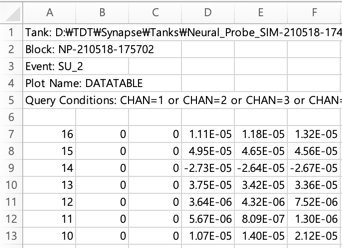     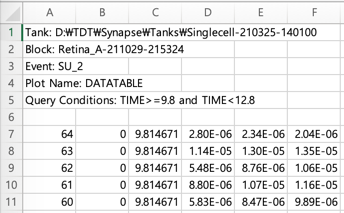

                - **7**번째 row부터 데이터 시작

                - channel number 기록되어 있음, chnnel이 여러 개 있음

                - row마다 시작 시간이 기록되어 있음

tic 
%                            filename, channelColumnIdx, timeColumnIdx, startRowIdx, startColIdx, sampleRate
reader.readMultiChannelFile("./data/전체.xlsx", 1,        3,             7,             4,           nan); %일단 파일을 불러옴

This file has 64 channels: 

ans =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


toc % 코드 실행 시간 측정. 오래 걸림.

경과 시간은 60.191255초입니다.


% readSingleChannelFromFile: 원하는 channel 하나만 가져오기

%                                      organoid, channel, month 
test_5 = reader.readSingleChannelFromFile(1, 8, 1)

test_5 =   channel - 속성 있음:

              organoidNum: 1.0000e+000
               channelNum: 8.0000e+000
                    month: 1.0000e+000
                       sf: 24.4141e+003
                  msPerTs: 40.9600e-003
              nTimestamps: 73.7270e+003
                startTime: 9.8147e+000
            endTimeApprox: 12.8345e+000
           durationApprox: 3.0198e+000
                        t: [1×73727 double]
                      raw: [1×73727 double]
                 filtered: []
        timestampsPrePeak: []
       timestampsPostPeak: []
          spikeTimestamps: []
    spikeTimestampsMatrix: []
           spikeWaveforms: []
                  nSpikes: []
                 PCScores: []
             explainedVar: []
                 clusters: []
                nClusters: []
        nSpikesPerCluster: []
     totalMeanSpikeStruct: []
         meanSpikesStruct: []
             ISIbeforePCA: []
              

% readManyChannelsFromFile: 모든 channel 다 읽어와 배열로 만들기

%                                           organoid,   month 
pixels_test6 = reader.readManyChannelsFromFile(1,       1 );

Reading 64 channels at once...

channel number = 1
sampling rate = 24414.060481Hz
starts at 9.814671, ends at 12.834488, duration = 3.019817
number of timestamps = 73727

channel number = 2
sampling rate = 24414.060481Hz
starts at 9.814671, ends at 12.834488, duration = 3.019817
number of timestamps = 73727

channel number = 3
sampling rate = 24414.060481Hz
starts at 9.814671, ends at 12.834488, duration = 3.019817
number of timestamps = 73727

channel number = 4
sampling rate = 24414.060481Hz
starts at 9.814671, ends at 12.834488, duration = 3.019817
number of timestamps = 73727

channel number = 5
sampling rate = 24414.060481Hz
starts at 9.814671, ends at 12.834488, duration = 3.019817
number of timestamps = 73727

channel number = 6
sampling rate = 24414.060481Hz
starts at 9.814671, ends at 12.834488, duration = 3.019817
number of timestamps = 73727

channel number = 7
sampling rate = 24414.060481Hz
starts at 9.814671, ends at 12.834488, duration = 3.019817
number of timestamps = 73


pixel1_test6_NEW = pixels_test6_NEW{1} % 64개 채널 중 첫 번째 채널을 선택

'pixels_test6_NEW'은(는) 정의되지 않은 변수입니다.